% Parameters for dynamics
m1 = param.m1; % mass of link 1 [kg]
m2 = param.m2; % mass of link 2 [kg]
m3 = param.m2; % mass of link 3 [kg]
m4 = param.m1; % mass of link 4 [kg]
m5 = param.m5; % mass of link 5 (trunk) [kg]

l1 = param.l1; % length of link n [m]
l2 = param.l2;
l3 = param.l2;
l4 = param.l1;
l5 = param.l5;

I1 = param.I1; % rotational inertia [kg m^2]
I2 = param.I2;
I3 = param.I2;
I4 = param.I1;
I5 = param.I5;


th1 = simout(:,1);
th2 = simout(:,2);
th3 = simout(:,3);
th4 = simout(:,4);
th5 = simout(:,5);

dth1 = simout(:,6);
dth2 = simout(:,7);
dth3 = simout(:,8);
dth4 = simout(:,9);
dth5 = simout(:,10);

% gen. coordinates after the impact
th1_plus = simout(:,1) + simout(:,2) + simout(:,3) + simout(:,4) - pi

th1_plus =     1.5976
    1.5967
    1.5944
    1.5908
    1.5862
    1.5807
    1.5744
    1.5675
    1.5600
    1.5521


th2_plus = -simout(:,4) + 2*pi;
th3_plus = -simout(:,3) - 2*pi;
th4_plus = -simout(:,2) + 2*pi;
th5_plus = simout(:,5) - simout(:,3) - pi;

for i=1:length(time)
    th1 = simout(i,1);
    th2 = simout(i,2);
    th3 = simout(i,3);
    th4 = simout(i,4);
    th5 = simout(i,5);
    
    dth1 = simout(i,6);
    dth2 = simout(i,7);
    dth3 = simout(i,8);
    dth4 = simout(i,9);
    dth5 = simout(i,10);
    
    dq_minus = [dth1;dth2;dth3;dth4;dth5];
    
    J_Psw_tip_minus = [- l4*sin(th1 + th2 + th3 + th4) - l2*sin(th1 + th2) - l1*sin(th1) - l3*sin(th1 + th2 + th3), - l4*sin(th1 + th2 + th3 + th4) - l2*sin(th1 + th2) - l3*sin(th1 + th2 + th3), - l4*sin(th1 + th2 + th3 + th4) - l3*sin(th1 + th2 + th3), -l4*sin(th1 + th2 + th3 + th4), 0;
        l4*cos(th1 + th2 + th3 + th4) + l2*cos(th1 + th2) + l1*cos(th1) + l3*cos(th1 + th2 + th3),   l4*cos(th1 + th2 + th3 + th4) + l2*cos(th1 + th2) + l3*cos(th1 + th2 + th3),   l4*cos(th1 + th2 + th3 + th4) + l3*cos(th1 + th2 + th3),  l4*cos(th1 + th2 + th3 + th4), 0];
    
    MM_minus = [
        I1 + I2 + I3 + I4 + I5 + (l1^2*m1)/4 + l1^2*m2 + l1^2*m3 + (l2^2*m2)/4 + l1^2*m4 + l2^2*m3 + l1^2*m5 + l2^2*m4 + (l3^2*m3)/4 + l2^2*m5 + l3^2*m4 + (l4^2*m4)/4 + (l5^2*m5)/4 + l1*l3*m3*cos(th2 + th3) + 2*l1*l3*m4*cos(th2 + th3) + l2*l4*m4*cos(th3 + th4) + l1*l5*m5*cos(th2 + th5) + l1*l2*m2*cos(th2) + 2*l1*l2*m3*cos(th2) + 2*l1*l2*m4*cos(th2) + 2*l1*l2*m5*cos(th2) + l2*l3*m3*cos(th3) + 2*l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + l2*l5*m5*cos(th5) + l1*l4*m4*cos(th2 + th3 + th4), I2 + I3 + I4 + I5 + (l2^2*m2)/4 + l2^2*m3 + l2^2*m4 + (l3^2*m3)/4 + l2^2*m5 + l3^2*m4 + (l4^2*m4)/4 + (l5^2*m5)/4 + (l1*l3*m3*cos(th2 + th3))/2 + l1*l3*m4*cos(th2 + th3) + l2*l4*m4*cos(th3 + th4) + (l1*l5*m5*cos(th2 + th5))/2 + (l1*l2*m2*cos(th2))/2 + l1*l2*m3*cos(th2) + l1*l2*m4*cos(th2) + l1*l2*m5*cos(th2) + l2*l3*m3*cos(th3) + 2*l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + l2*l5*m5*cos(th5) + (l1*l4*m4*cos(th2 + th3 + th4))/2, I3 + I4 + (l3^2*m3)/4 + l3^2*m4 + (l4^2*m4)/4 + (l1*l3*m3*cos(th2 + th3))/2 + l1*l3*m4*cos(th2 + th3) + (l2*l4*m4*cos(th3 + th4))/2 + (l2*l3*m3*cos(th3))/2 + l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + (l1*l4*m4*cos(th2 + th3 + th4))/2, I4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l3*l4*m4*cos(th4))/2 + (l1*l4*m4*cos(th2 + th3 + th4))/2, I5 + (l5^2*m5)/4 + (l1*l5*m5*cos(th2 + th5))/2 + (l2*l5*m5*cos(th5))/2;
        I2 + I3 + I4 + I5 + (l2^2*m2)/4 + l2^2*m3 + l2^2*m4 + (l3^2*m3)/4 + l2^2*m5 + l3^2*m4 + (l4^2*m4)/4 + (l5^2*m5)/4 + (l1*l3*m3*cos(th2 + th3))/2 + l1*l3*m4*cos(th2 + th3) + l2*l4*m4*cos(th3 + th4) + (l1*l5*m5*cos(th2 + th5))/2 + (l1*l2*m2*cos(th2))/2 + l1*l2*m3*cos(th2) + l1*l2*m4*cos(th2) + l1*l2*m5*cos(th2) + l2*l3*m3*cos(th3) + 2*l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + l2*l5*m5*cos(th5) + (l1*l4*m4*cos(th2 + th3 + th4))/2,                                                                                                                                                                                                               I2 + I3 + I4 + I5 + (l2^2*m2)/4 + l2^2*m3 + l2^2*m4 + (l3^2*m3)/4 + l2^2*m5 + l3^2*m4 + (l4^2*m4)/4 + (l5^2*m5)/4 + l2*l4*m4*cos(th3 + th4) + l2*l3*m3*cos(th3) + 2*l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + l2*l5*m5*cos(th5),                                                                                             I3 + I4 + (l3^2*m3)/4 + l3^2*m4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l2*l3*m3*cos(th3))/2 + l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4),                                     I4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l3*l4*m4*cos(th4))/2,                               (m5*l5^2)/4 + (l2*m5*cos(th5)*l5)/2 + I5;
        I3 + I4 + (l3^2*m3)/4 + l3^2*m4 + (l4^2*m4)/4 + (l1*l3*m3*cos(th2 + th3))/2 + l1*l3*m4*cos(th2 + th3) + (l2*l4*m4*cos(th3 + th4))/2 + (l2*l3*m3*cos(th3))/2 + l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4) + (l1*l4*m4*cos(th2 + th3 + th4))/2,                                                                                                                                                                                                                                                                                                 I3 + I4 + (l3^2*m3)/4 + l3^2*m4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l2*l3*m3*cos(th3))/2 + l2*l3*m4*cos(th3) + l3*l4*m4*cos(th4),                                                                                                                                                                       I3 + I4 + (l3^2*m3)/4 + l3^2*m4 + (l4^2*m4)/4 + l3*l4*m4*cos(th4),                                                                   (m4*l4^2)/4 + (l3*m4*cos(th4)*l4)/2 + I4,                                                                      0;
        I4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l3*l4*m4*cos(th4))/2 + (l1*l4*m4*cos(th2 + th3 + th4))/2,                                                                                                                                                                                                                                                                                                                                                                      I4 + (l4^2*m4)/4 + (l2*l4*m4*cos(th3 + th4))/2 + (l3*l4*m4*cos(th4))/2,                                                                                                                                                                                                (m4*l4^2)/4 + (l3*m4*cos(th4)*l4)/2 + I4,                                                                                           (m4*l4^2)/4 + I4,                                                                      0;
        I5 + (l5^2*m5)/4 + (l1*l5*m5*cos(th2 + th5))/2 + (l2*l5*m5*cos(th5))/2,                                                                                                                                                                                                                                                                                                                                                                                                    (m5*l5^2)/4 + (l2*m5*cos(th5)*l5)/2 + I5,                                                                                                                                                                                                                                       0,                                                                                                          0,                                                       (m5*l5^2)/4 + I5];
    
    dq_plus = (eye(5)-inv(MM_minus)*J_Psw_tip_minus.'*inv(J_Psw_tip_minus*inv(MM_minus)*J_Psw_tip_minus.')*J_Psw_tip_minus)*dq_minus;
    
    dth1_plus(i,:) = dq_plus(1);
    dth2_plus(i,:) = dq_plus(2);
    dth3_plus(i,:) = dq_plus(3);
    dth4_plus(i,:) = dq_plus(4);
    dth5_plus(i,:) = dq_plus(5);    
end

%
alpha = pi - (2*simout(:,1) + simout(:,2))/2

alpha =     1.6774
    1.6836
    1.6895
    1.6952
    1.7008
    1.7061
    1.7112
    1.7161
    1.7208
    1.7254


dalpha = - (2*simout(:,6) + simout(:,7))/2

dalpha =     1.4781
    1.4196
    1.3651
    1.3130
    1.2632
    1.2160
    1.1718
    1.1310
    1.0937
    1.0601



% alpha if impact happens
alpha_plus = pi - (2*th1_plus + th2_plus)/2

alpha_plus =     1.4131
    1.4197
    1.4262
    1.4328
    1.4393
    1.4457
    1.4521
    1.4583
    1.4644
    1.4703


dalpha_plus = - (2*dth1_plus + dth2_plus)/2

dalpha_plus =     1.2397
    1.1815
    1.1260
    1.0721
    1.0200
    0.9702
    0.9233
    0.8795
    0.8392
    0.8024



alpha_ref = pi - (2*ocl_traj.simout(:,1)+ocl_traj.simout(:,2))/2

alpha_ref =     1.4131
    1.4343
    1.4532
    1.4699
    1.4843
    1.4965
    1.5069
    1.5161
    1.5242
    1.5313


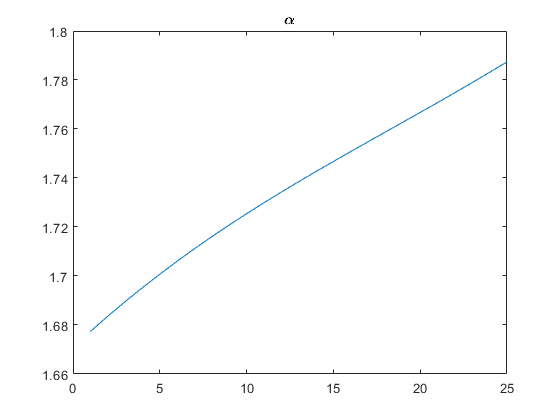

figure()
plot(alpha)
title('\alpha')

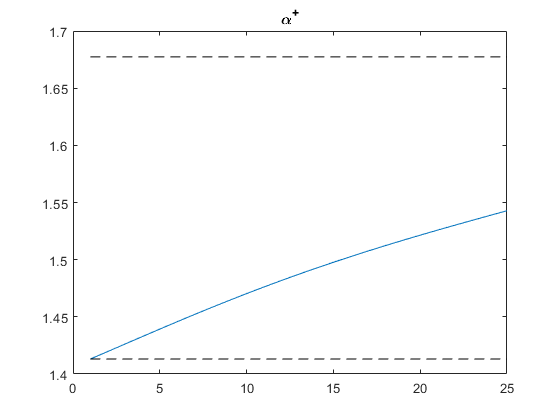


figure()
plot(alpha_plus)
hold on
plot([1, length(alpha_plus)],[alpha_ref(1), alpha_ref(1)],'k--')
plot([1, length(alpha_plus)],[alpha_ref(end), alpha_ref(end)],'k--')
title('\alpha^+')

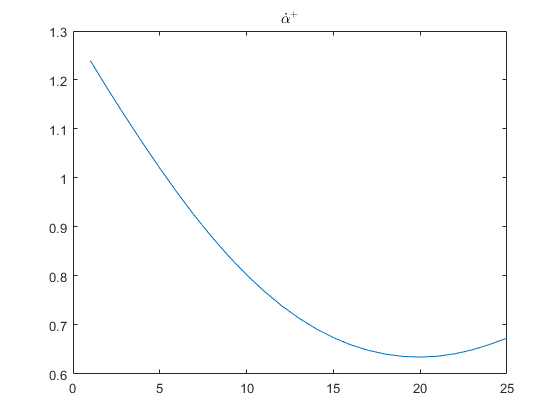


figure()
plot(dalpha_plus)
title('$\dot{\alpha}^+$', 'Interpreter','latex')